% Contributors: Mustafa Saraoğlu, Laura Slabon, Erik Noack, Müjdat Korkmaz, Marta Valdes Martin

# Before Getting Started

Before starting with the documentation, please read the **README.md** file located at the root of the project directory.

# Getting Started with MOBATSim

MOBATSim consists of several modular elements, ranging from MATLAB code to Simulink models, a Graphical User Interface (GUI), and live script documentation that includes LaTeX formulas and explanations of specific components of MOBATSim. Given the complexity of the documentation, fitting everything into a single live script would be exhaustive. Therefore, we have decided to split the documentation into several separate live script files, each focused on a specific subject and level of detail.

Once the **"GettingStarted.mlx"** document is completed, the overall structure of MOBATSim and how it works will be easier to understand. The next step is to review the **"Documentation.mlx"** file, which provides more detailed information about MOBATSim, focusing on its implementation and functionality. Based on the areas of interest, additional documentation files can be explored. For example, information on the implementation of vehicle models is available in **"VehicleMotionPlanningControl.mlx"**, and details about how the map is generated and visualized can be found in **"MapStructureVisualization.mlx"**.

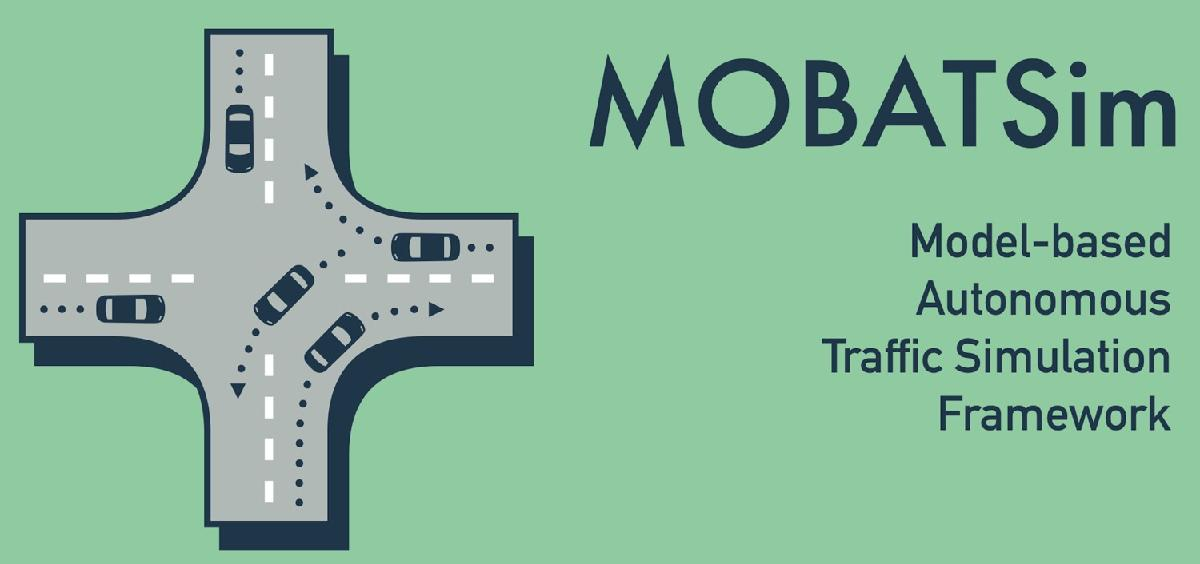

# Starting the Simulation and Visualization

MOBATSim includes a project file that contains the Simulink files and their paths. To open the project, double-click on **MOBATSim.prj**. A GUI will appear, which can be used to start the simulation. Simply click the **Start Simulation** button and wait for the simulation to begin.

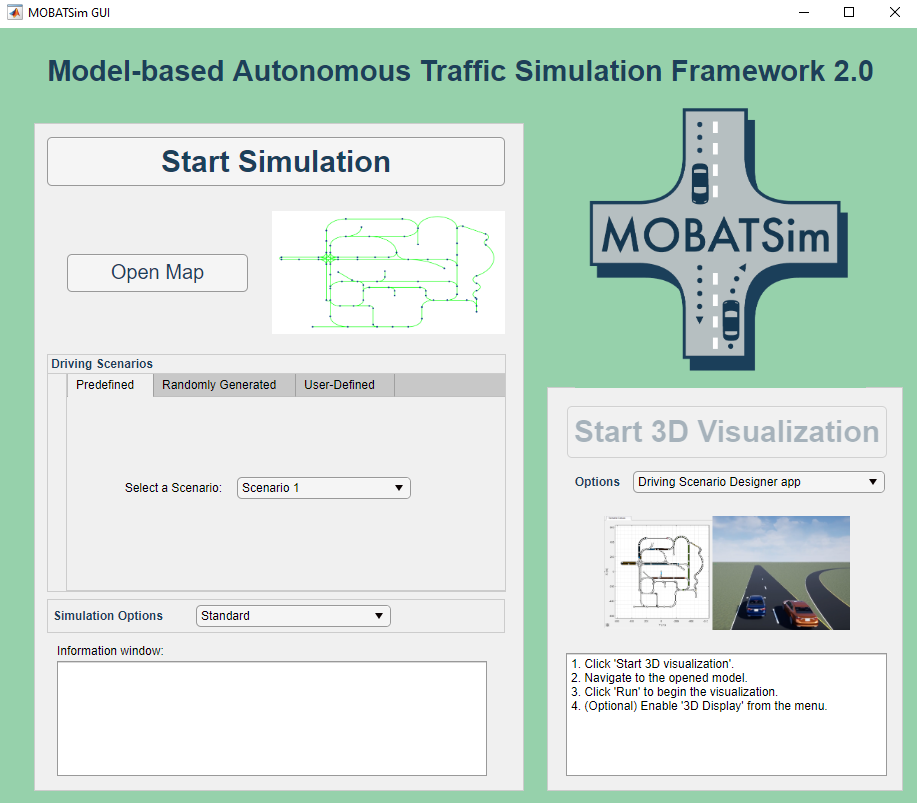

The MOBATSim Simulink model will automatically open and run to start the simulation. The map consists of nodes and edges displayed on a 2D plot. Vehicles appear as red circles, with their speeds shown in meters per second. Roads are represented in bright green, and the planned paths of the vehicles are dynamically highlighted in different colors. At this stage, the simulation runs using the Simulink model and the corresponding MATLAB m-files, while simultaneously logging vehicle data. Therefore, the simulation must be completed before the user can proceed with further visualization.

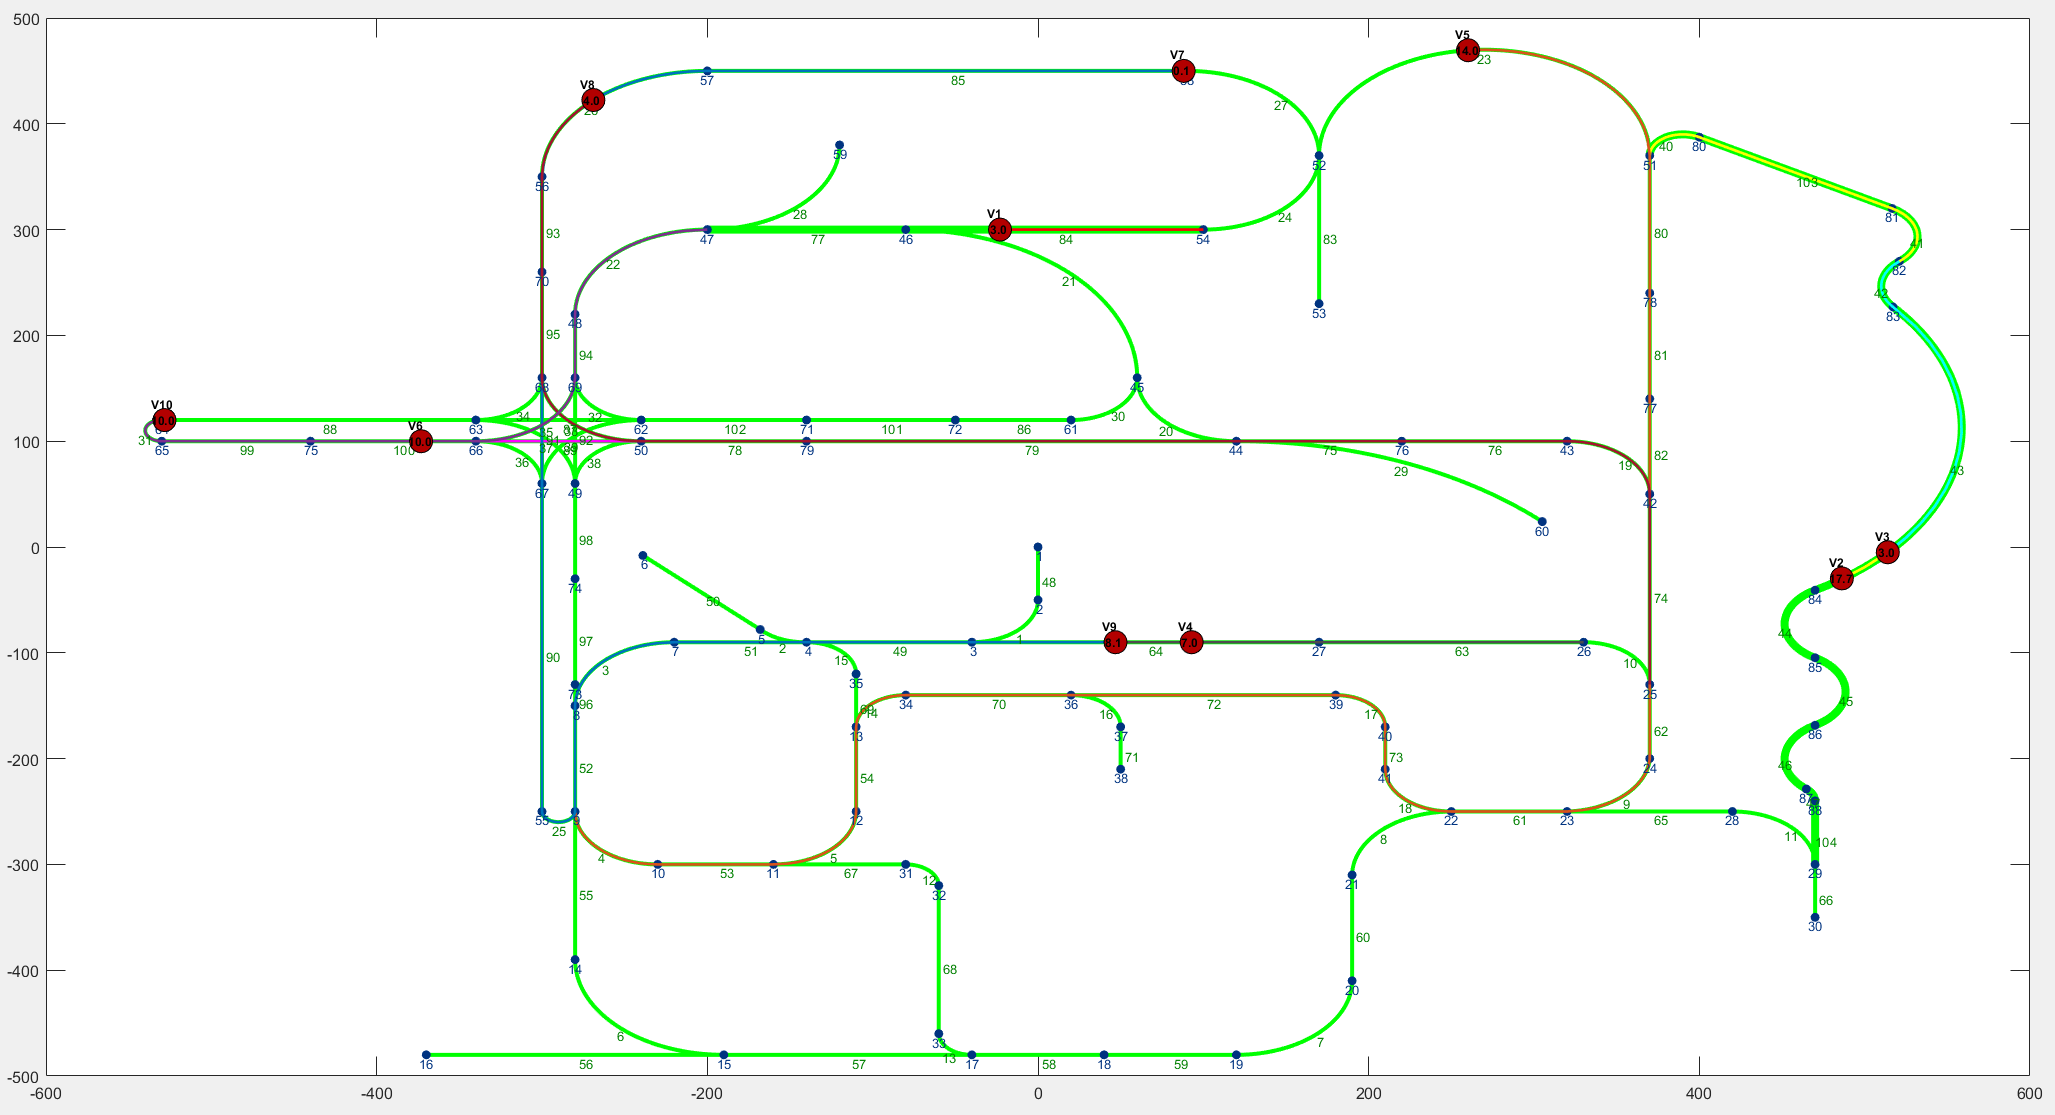

After completing the simulation without errors, the logged vehicle data, along with timestamps, is saved in the base workspace for further analysis or visualization. MOBATSim supports the following visualization options:

- **Using Driving Scenario Designer app**

- **Using Bird's-Eye Scope**

- **Simulink 3D Animation**

## **Using Driving Scenario Designer app**

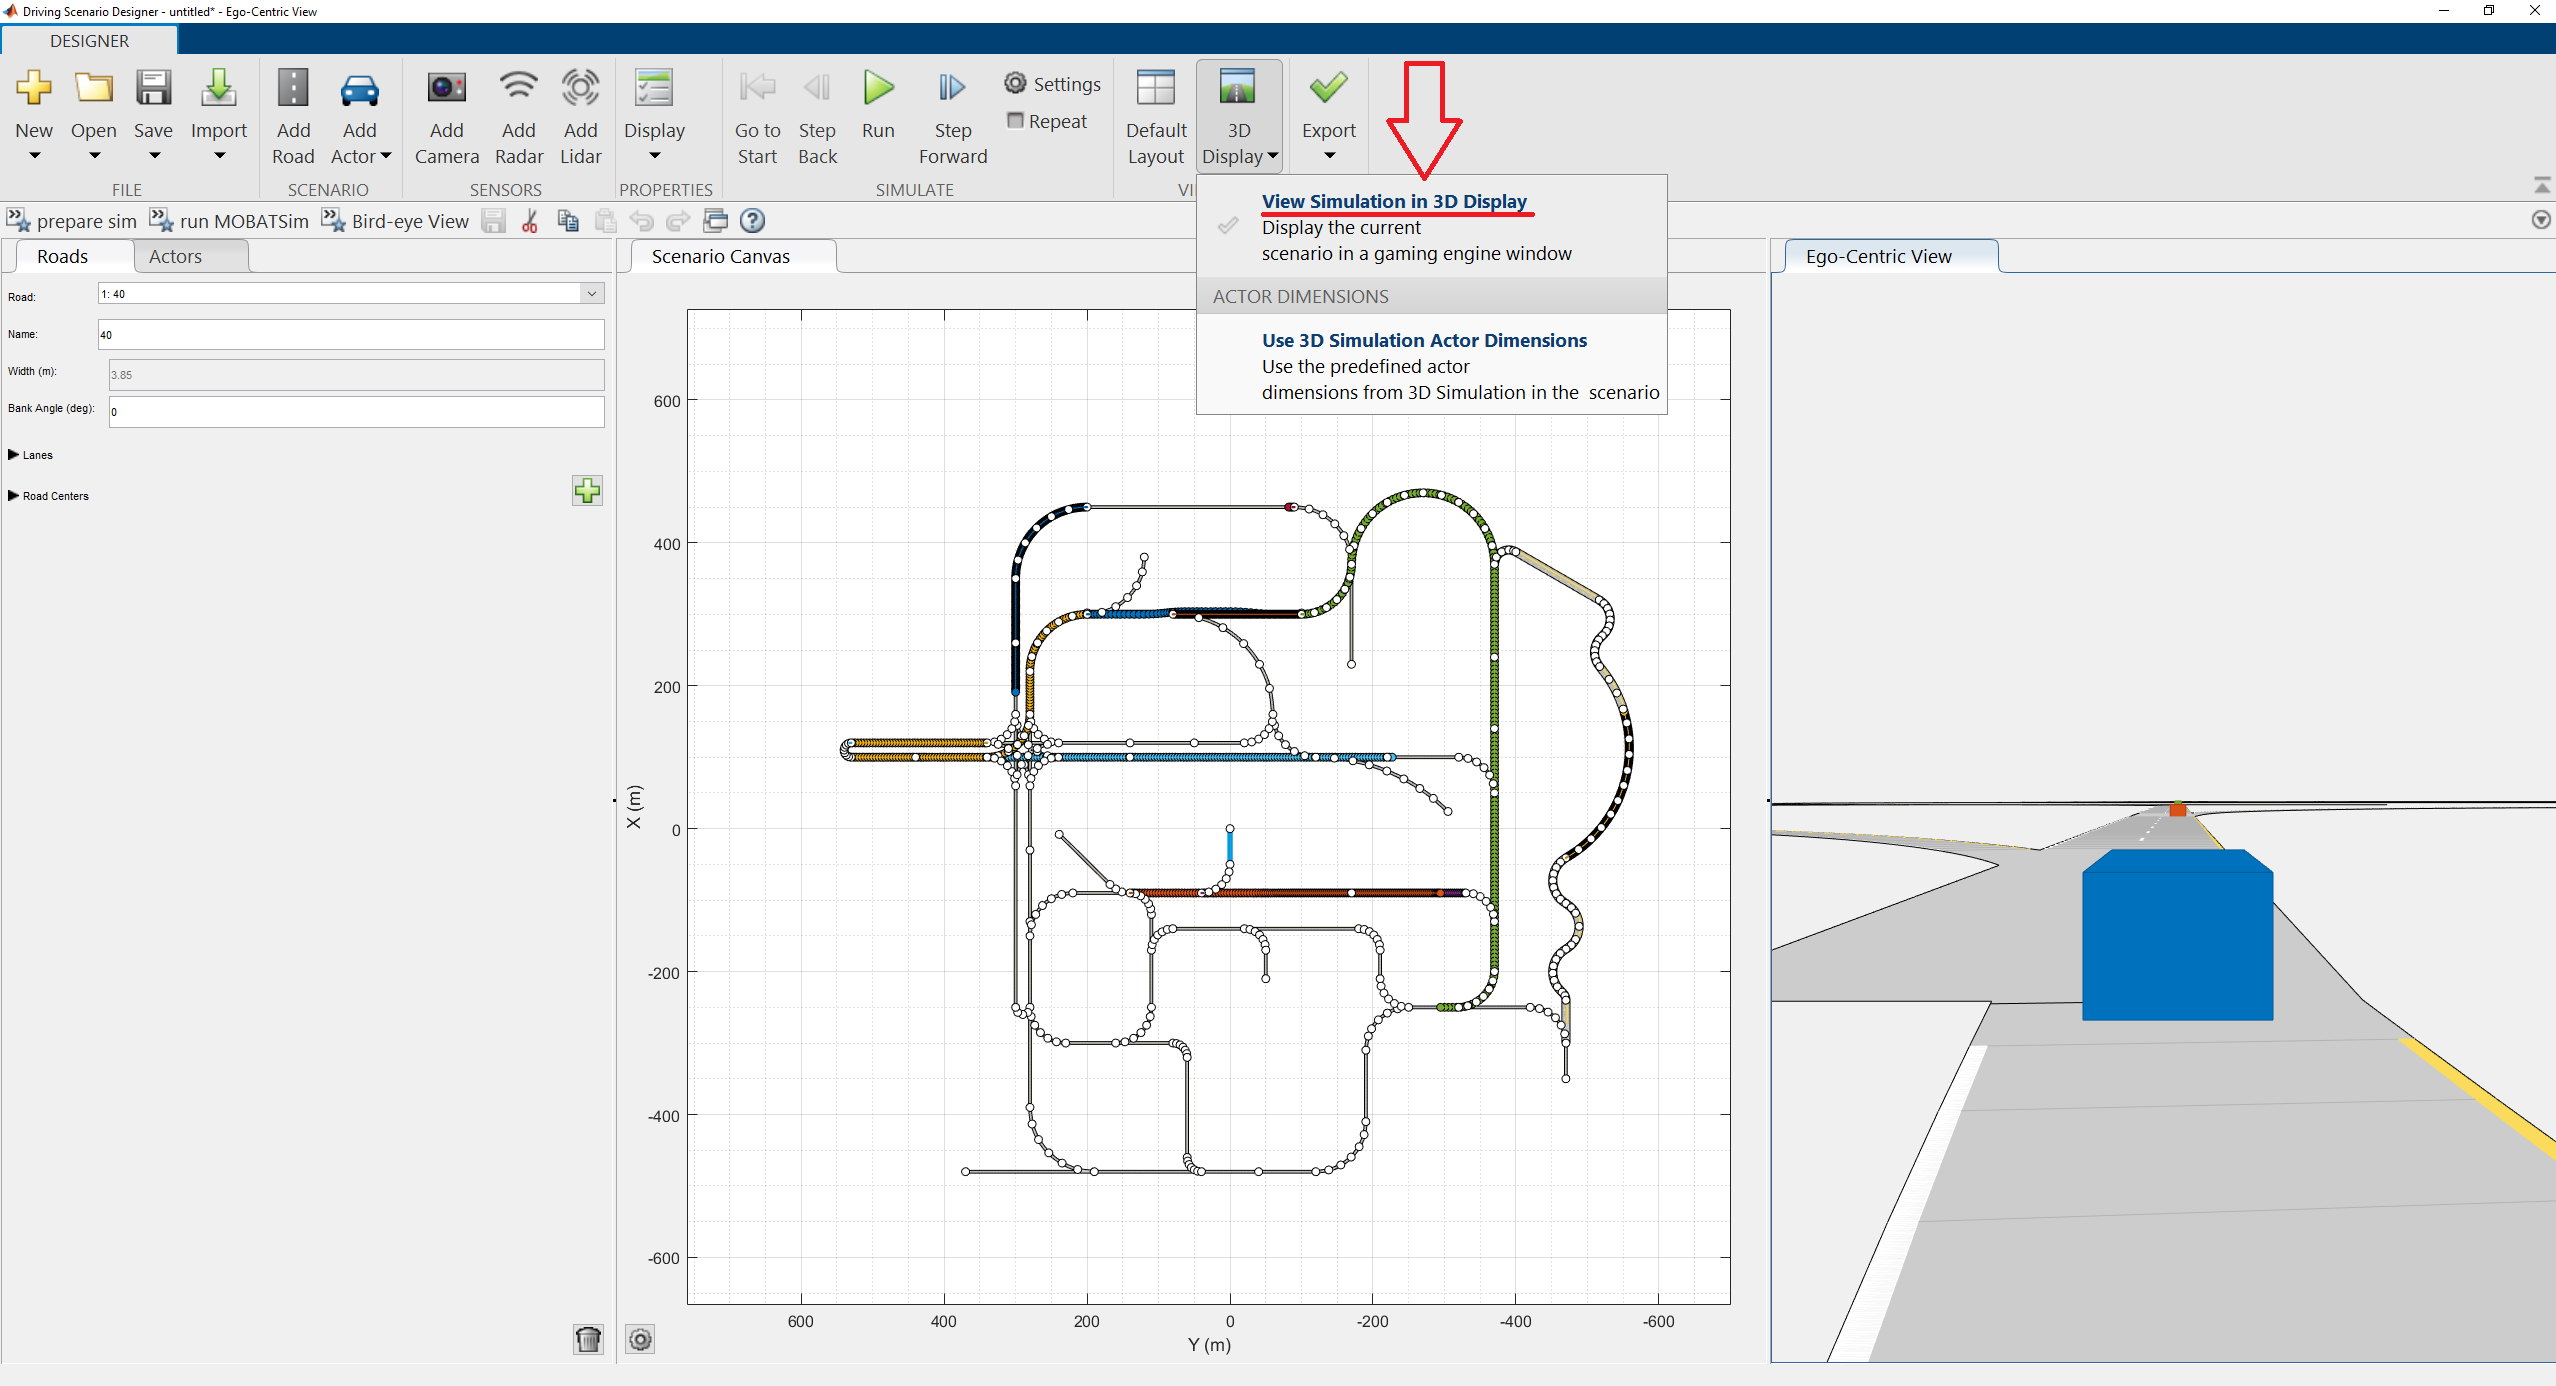

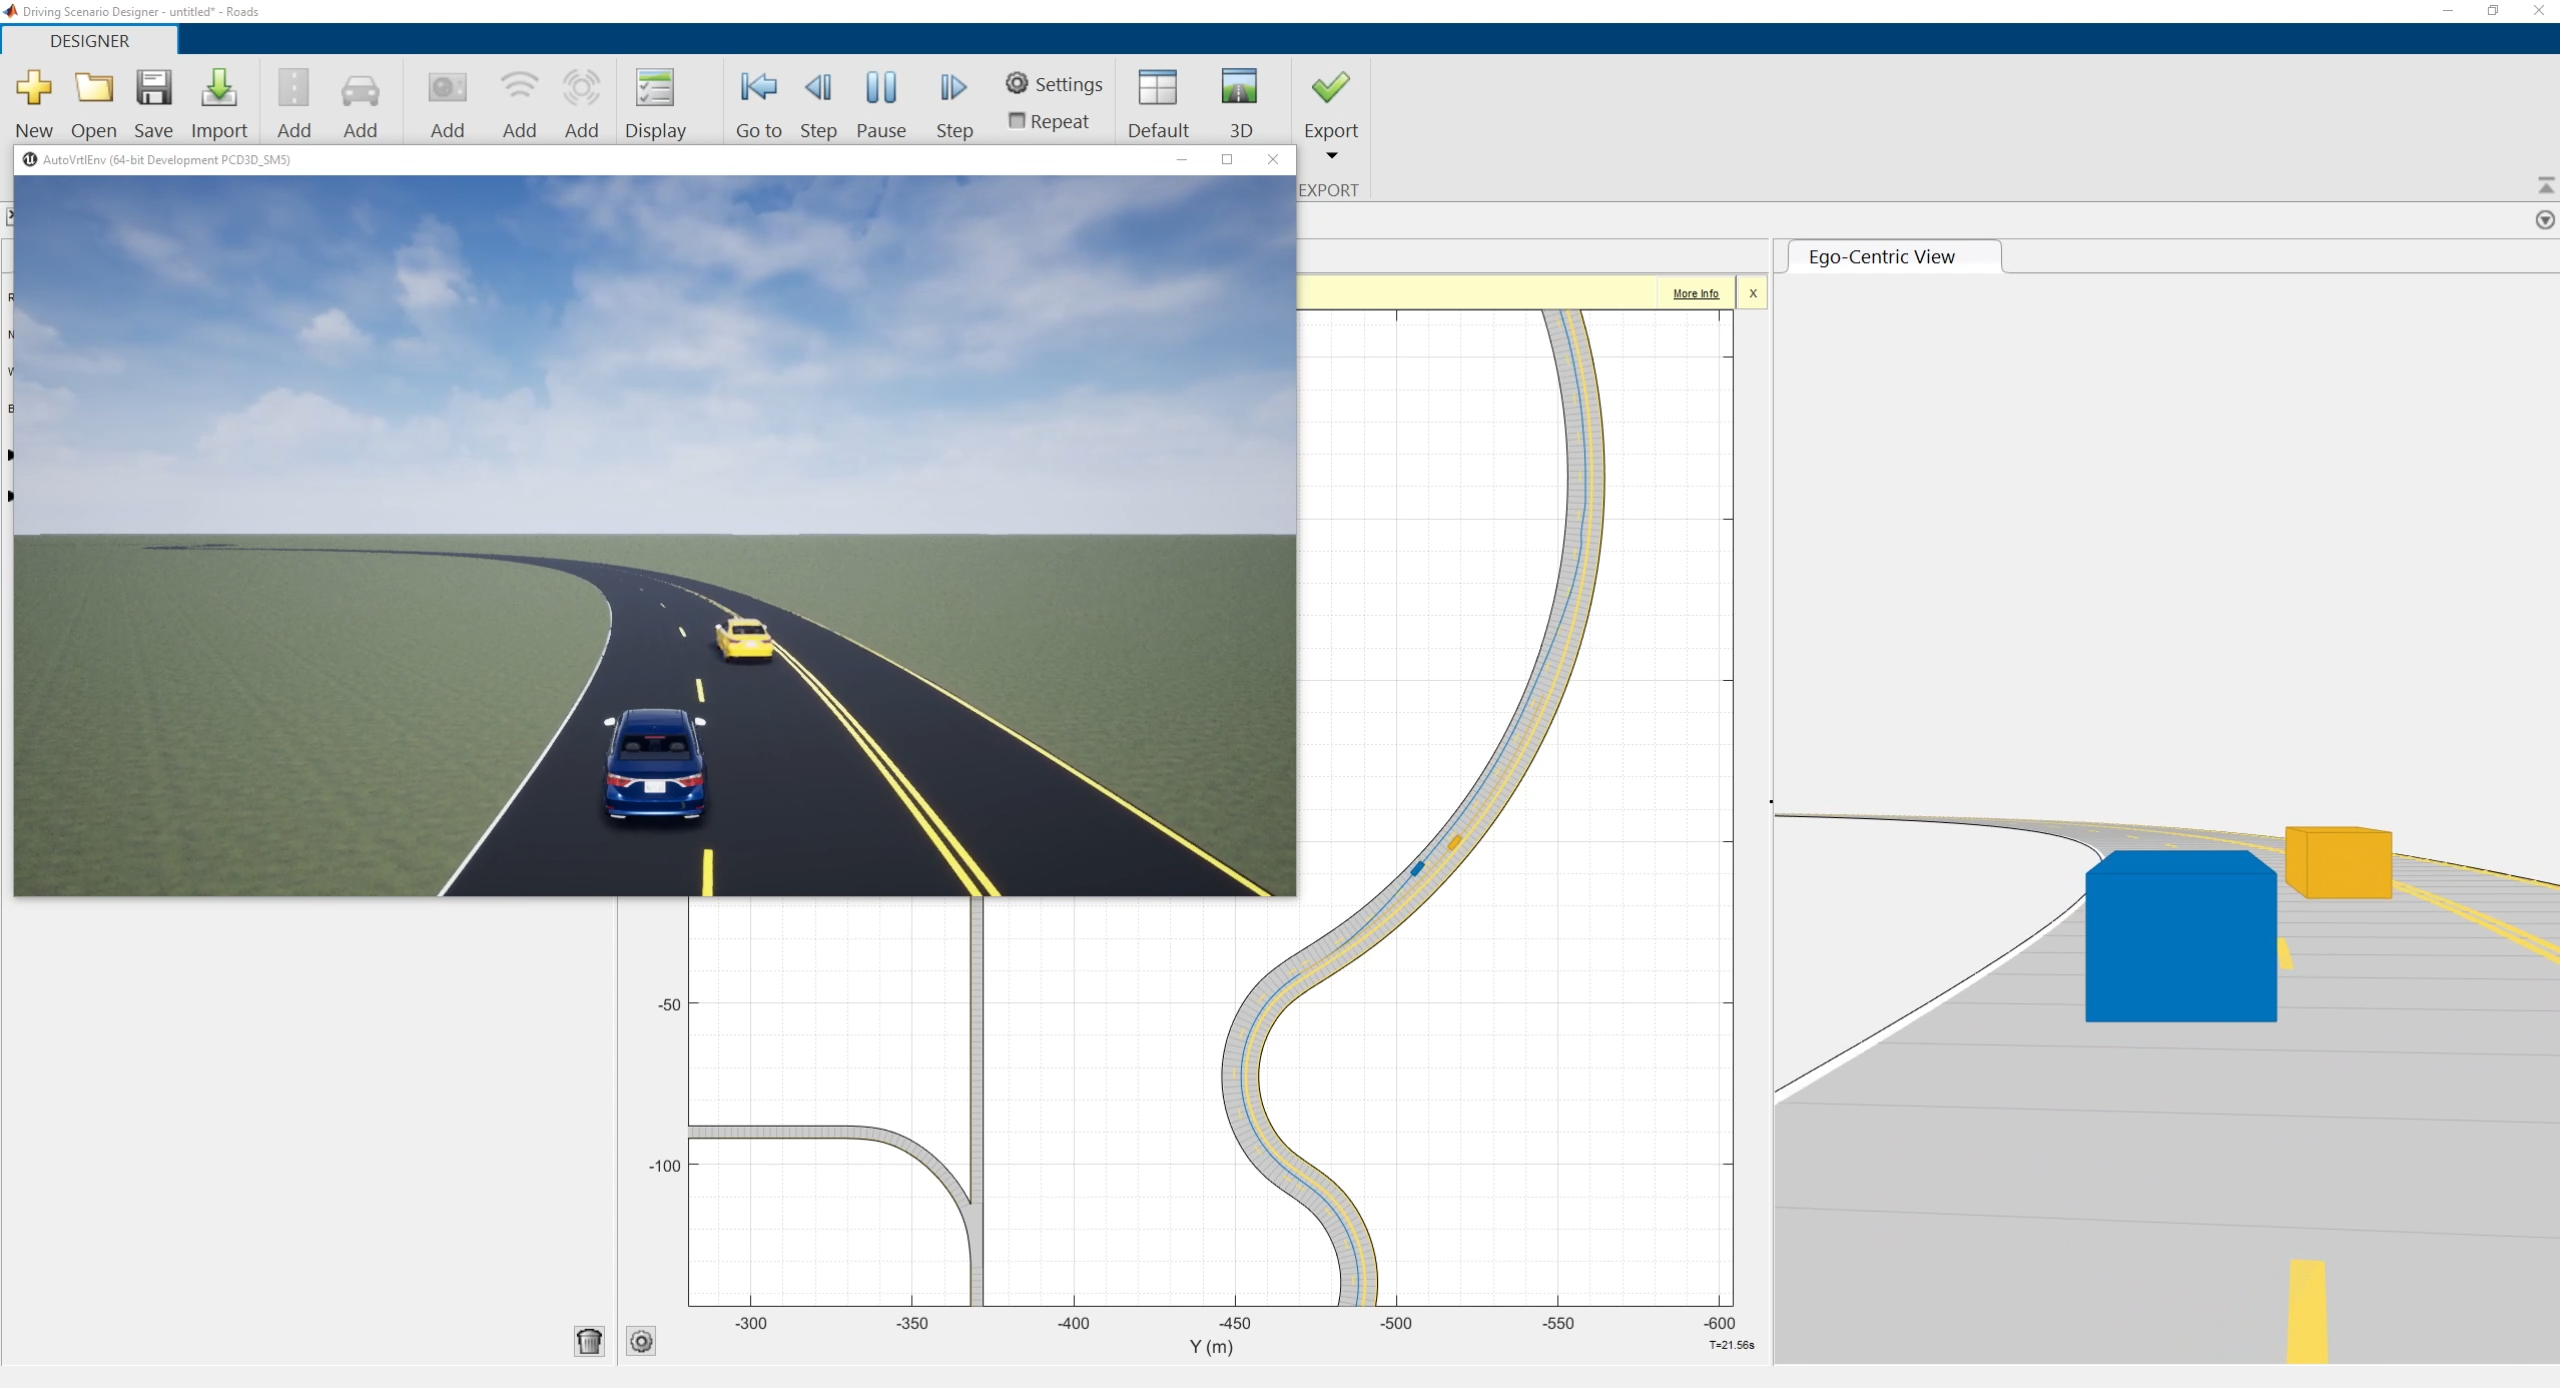

## Using Bird's-Eye Scope

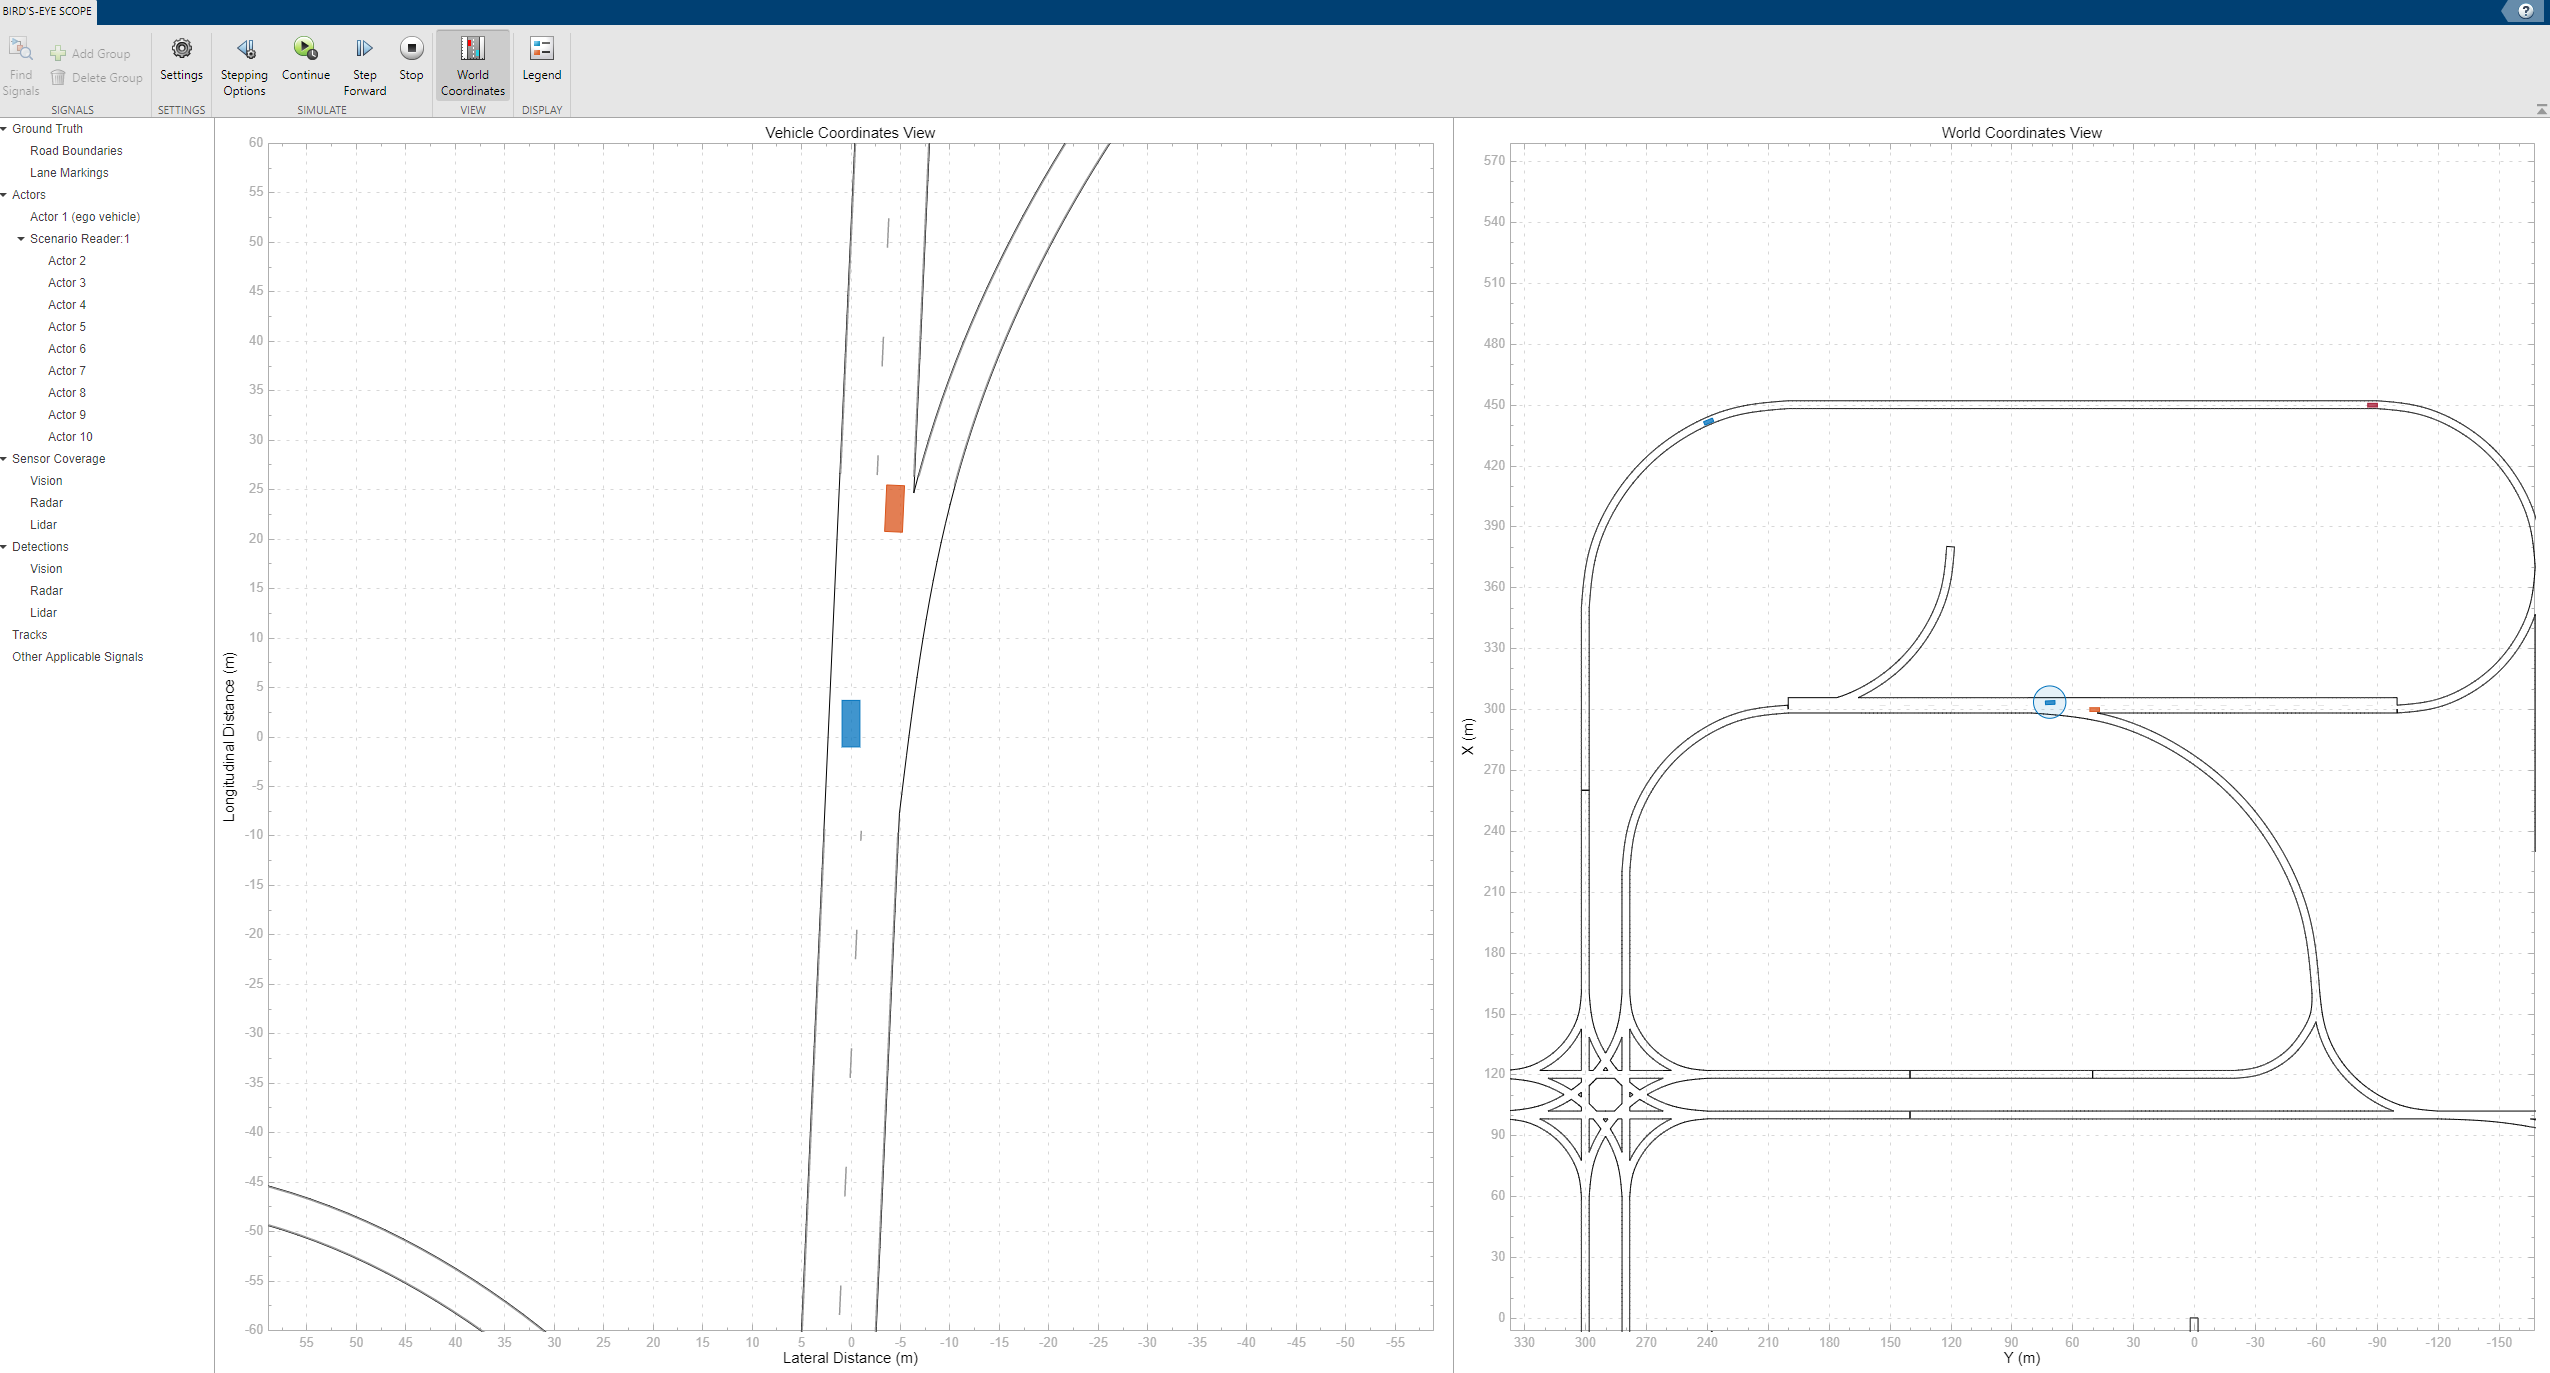

## Simulink 3D Animation

This map is obsolete, and the extended parts of MOBATSim, such as double lane roads, have not been applied to this map. Other visualization methods explained above are much more accurate and useful for scientific purposes.

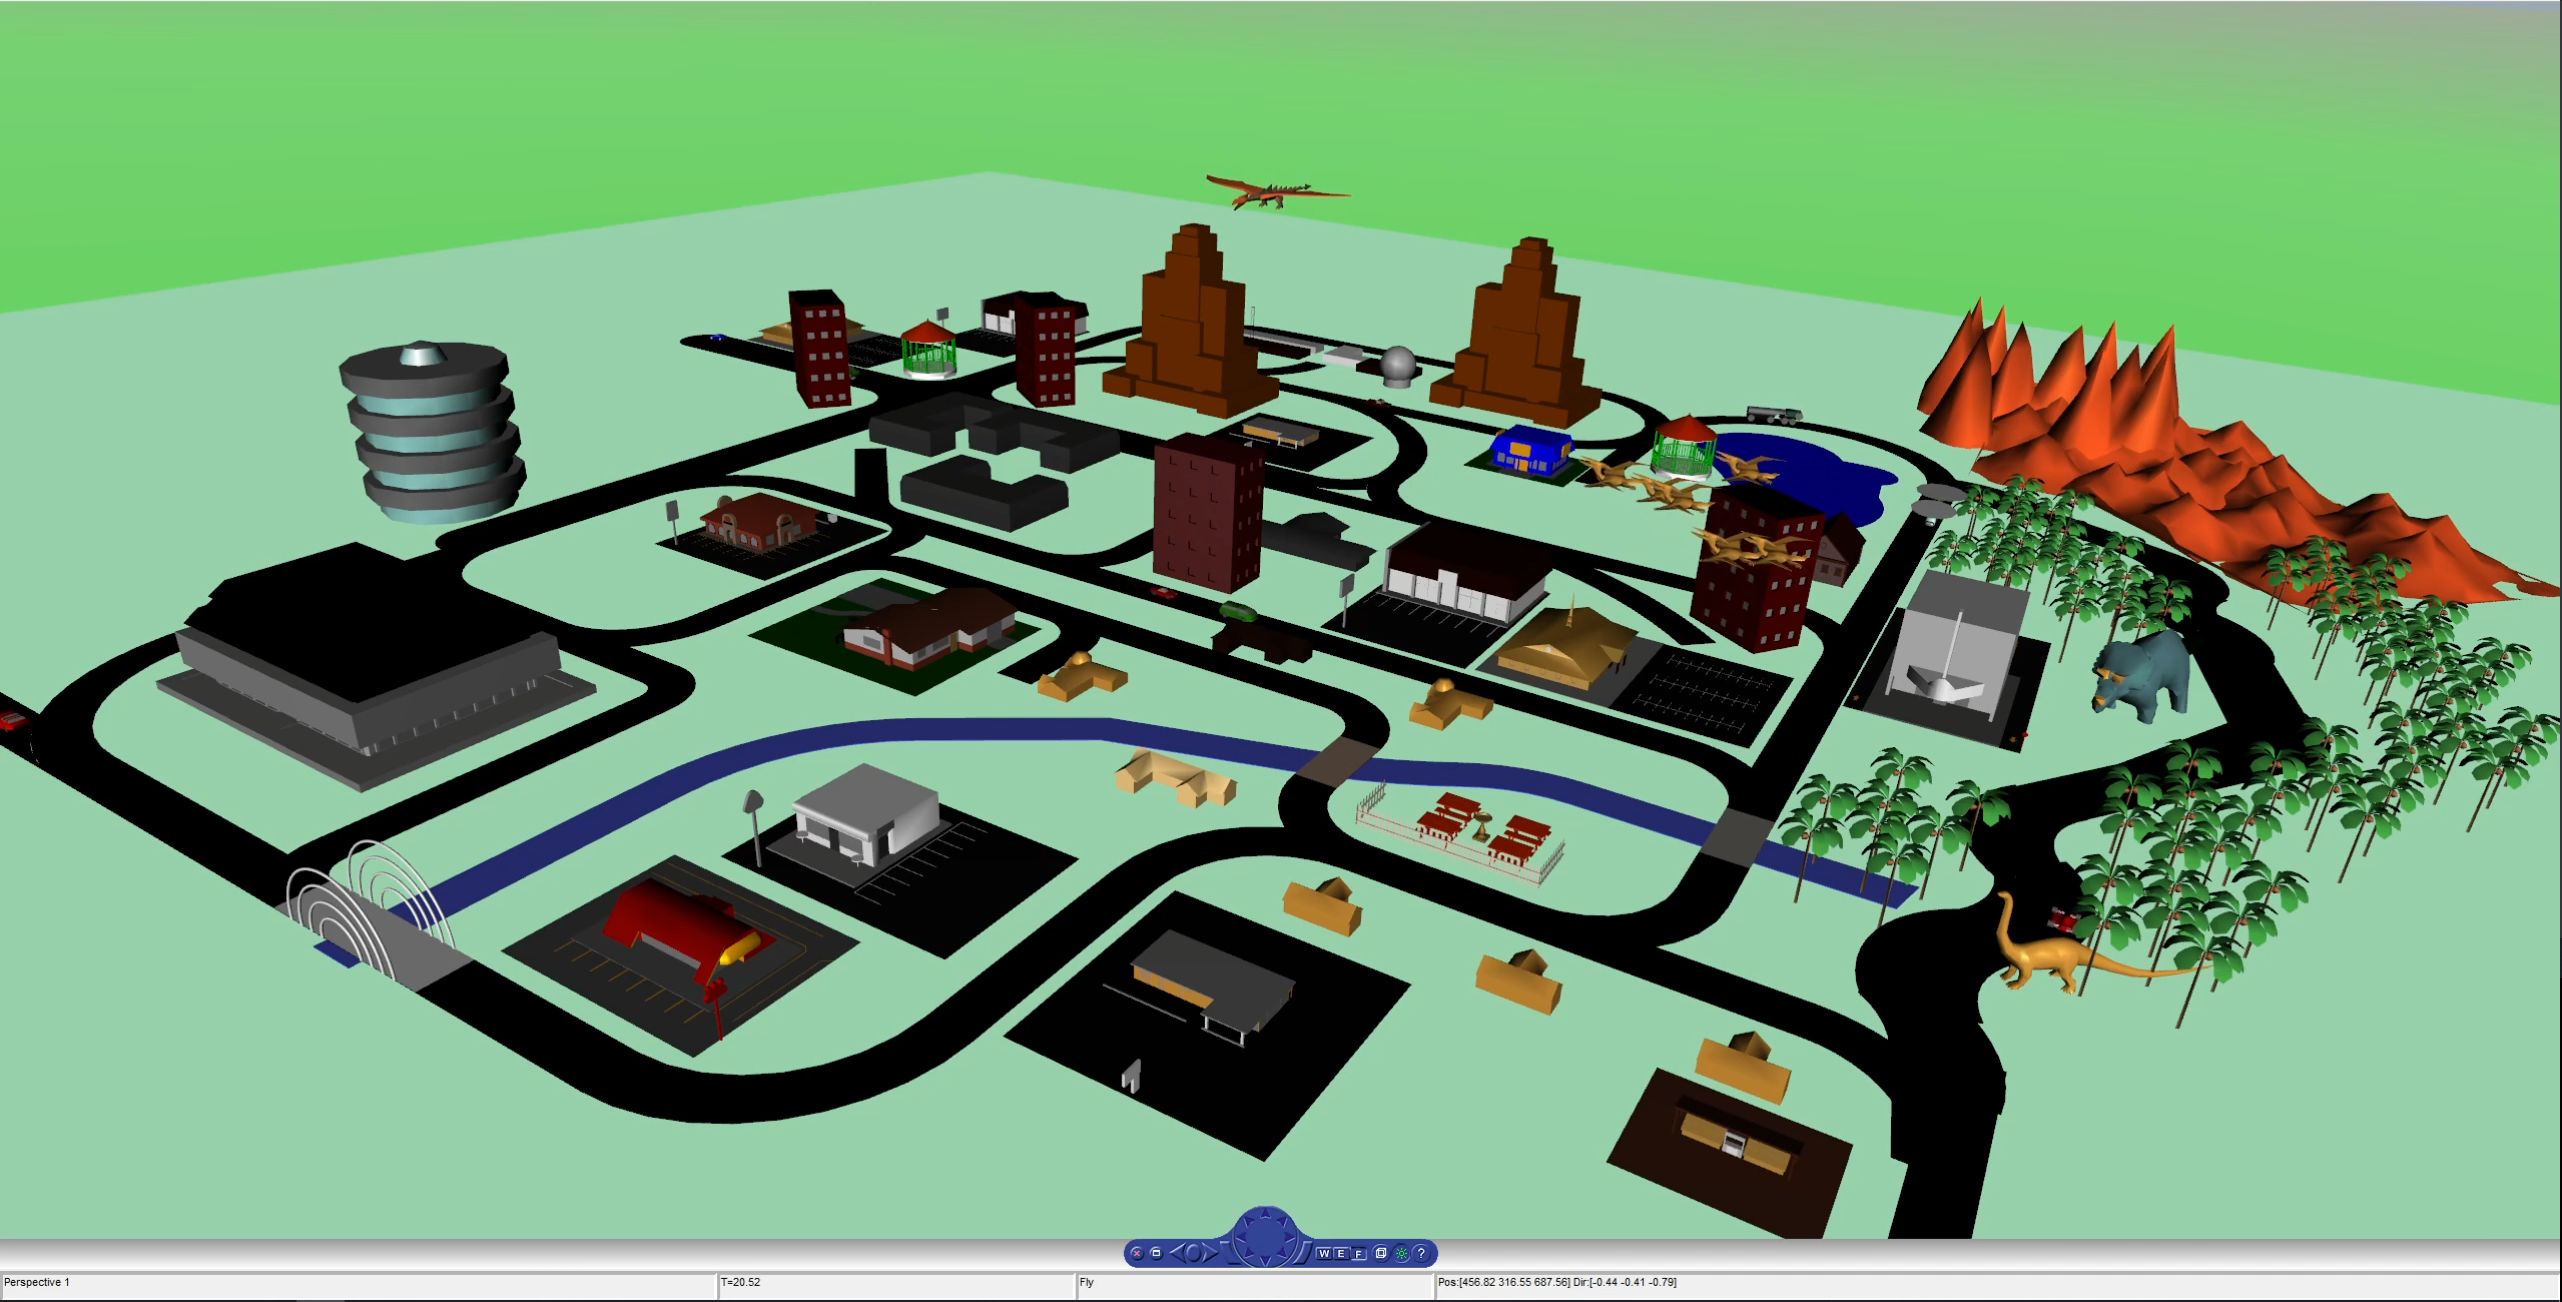

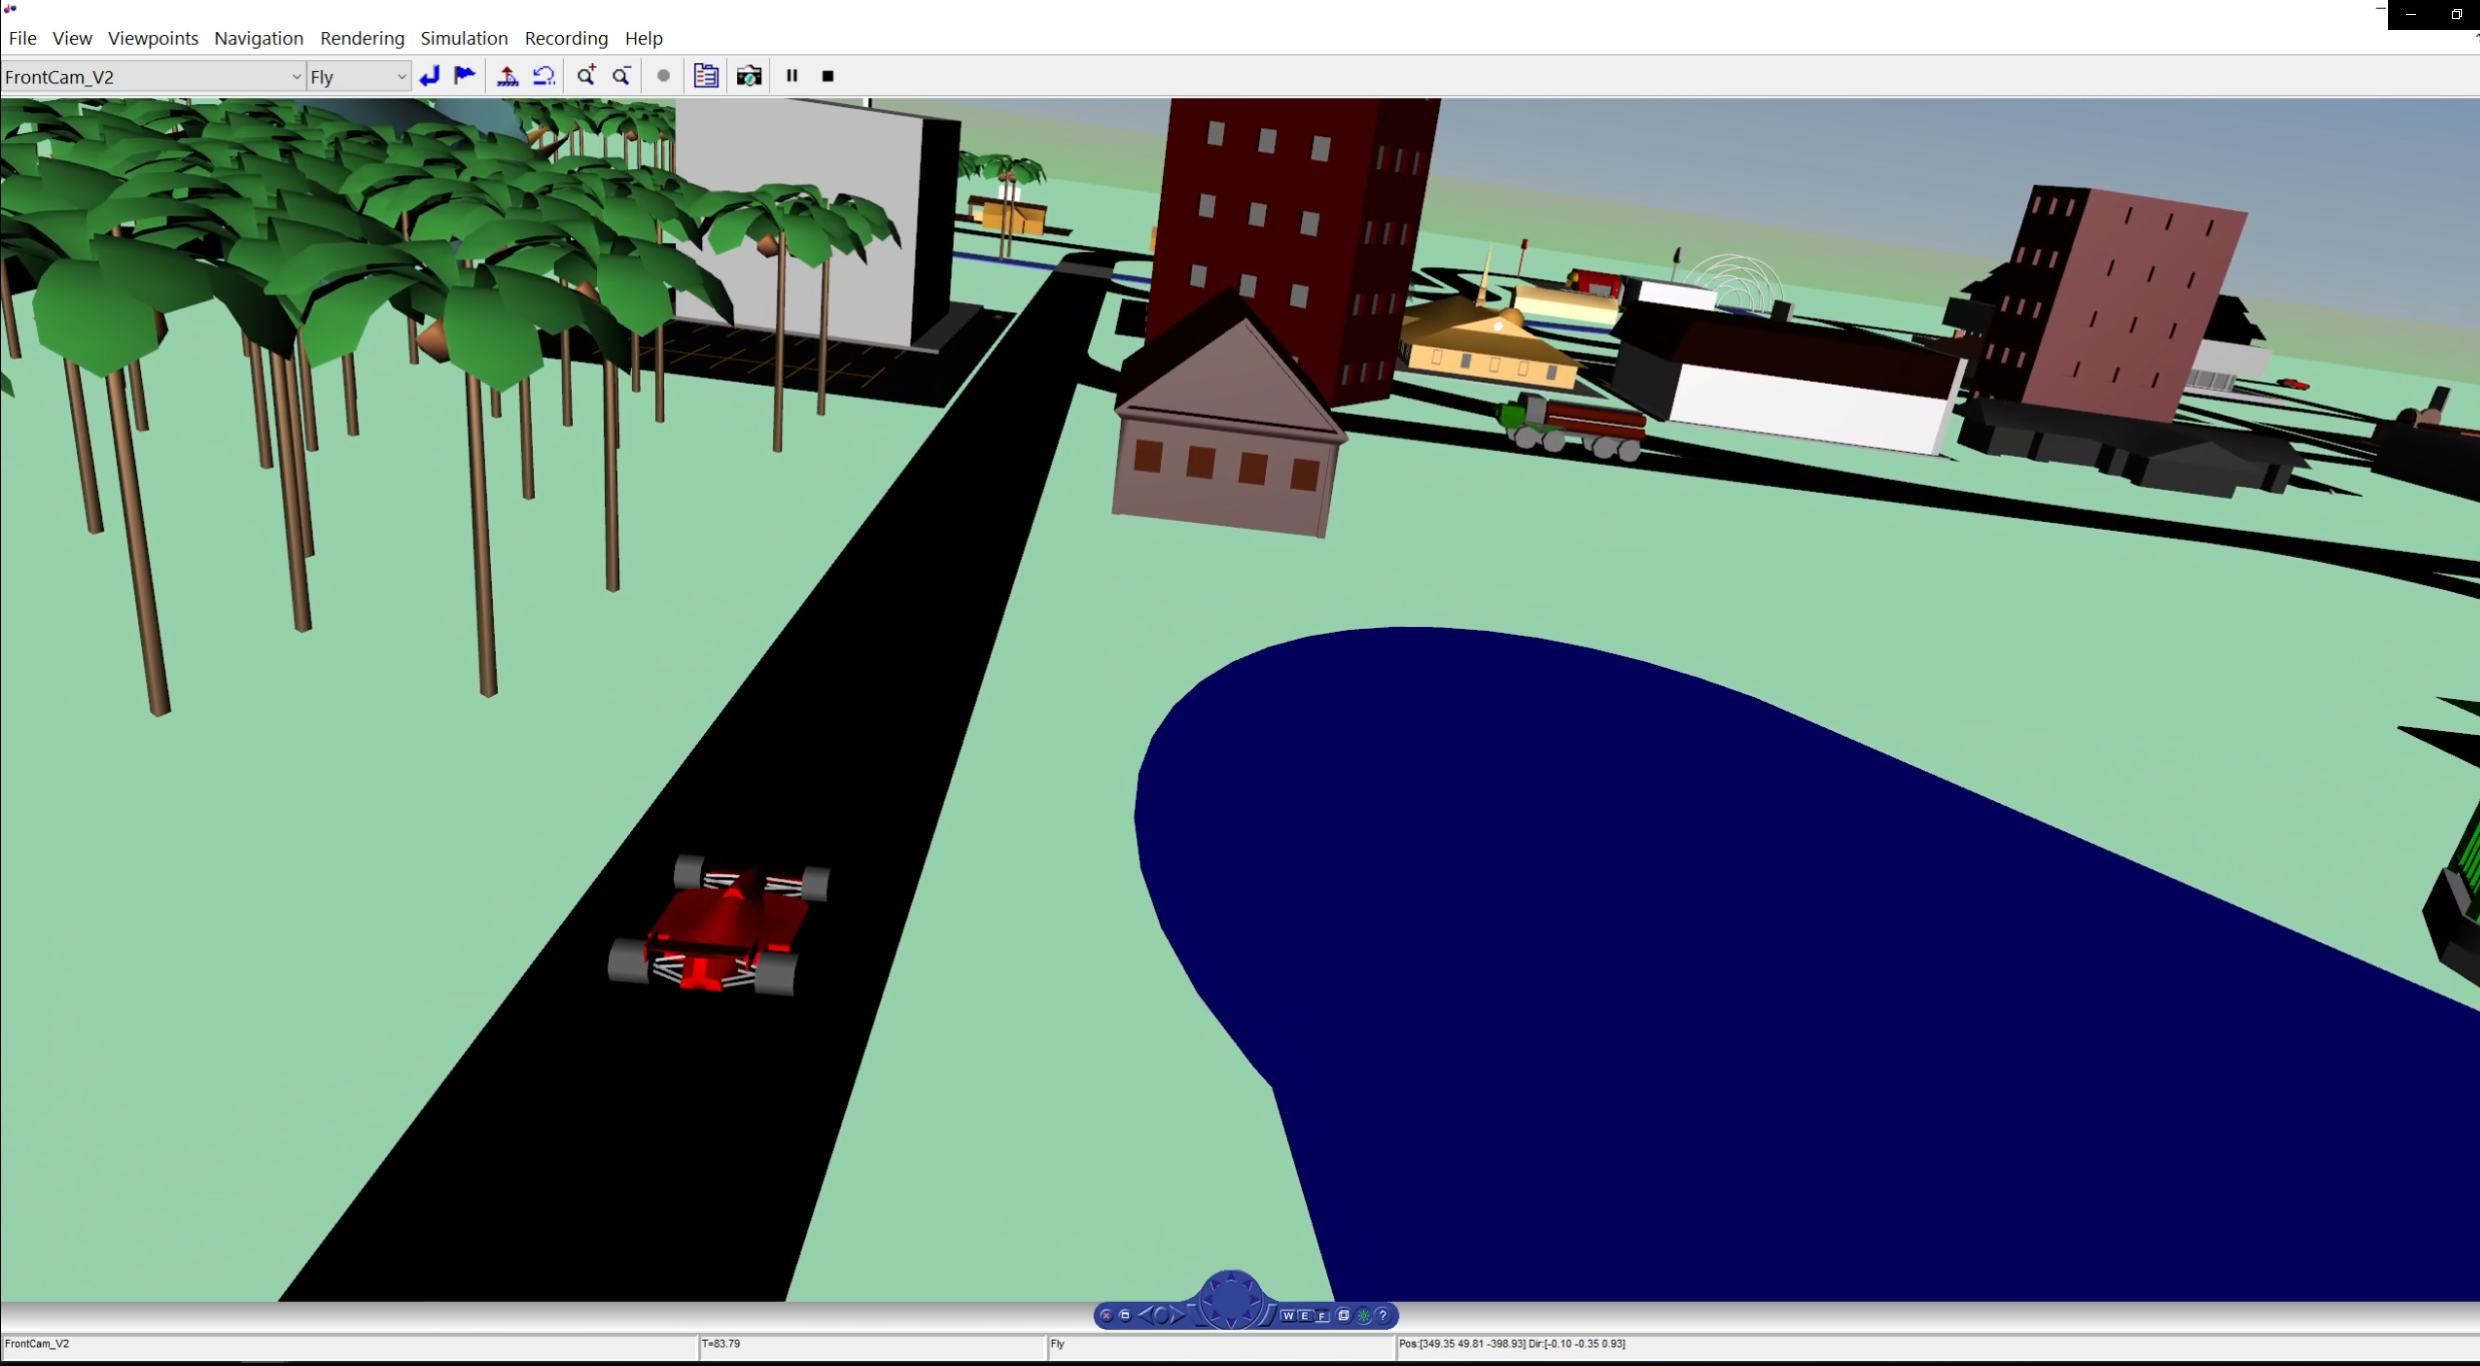

# -----------------------------------------------------------------------------

# Tutorials

Now you know how to run the simulation but the best way to learn how MOBATSim works is to interact with it and make changes. In the live script *docs/Documentation.mlx*, you will find a more detailed and in-depth workflow of MOBATSim. However the tutorials below are designed to provide you a quick intuition about MOBATSim without reading the whole documentation.

## 1- Modifying Starting and Destination Points

Next, locate the initial driving scenario file. A driving scenario defines the starting points, destination points, and maximum speeds of the vehicles. You can find it by searching for the function: `src/Scripts/Load Data/load_scenario.m`. Inside this file, you will find 10 starting points and destination points for 10 vehicles. Try modifying some of these points. Please note that the roads are one-way, so ensure that the destination points are reachable from the starting points.

After modifying some of the `startingPoints`, `destinationPoints`, and `maxSpeeds`, proceed to run the simulation with:

## 2- Debugging the Simulation and Viewing Vehicle States

Let's start the simulation, then pause it to inspect the state variables at a specific time. The task is to select a block in the Simulink model and interrupt the execution by placing a **conditional breakpoint**.

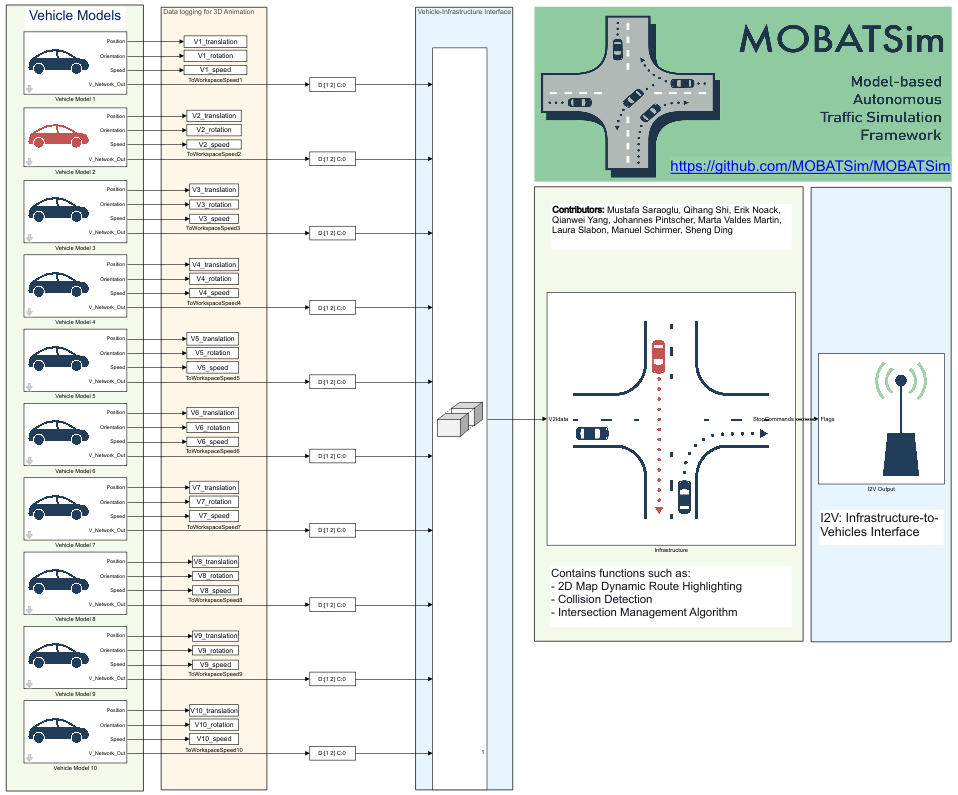

Let's zoom in on **Vehicle Model 1** and left-click on the bottom-left corner (on the small arrow that appears) to reveal its contents.

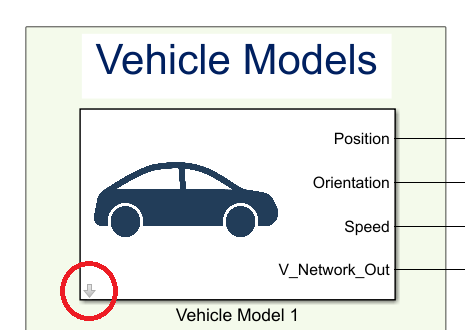

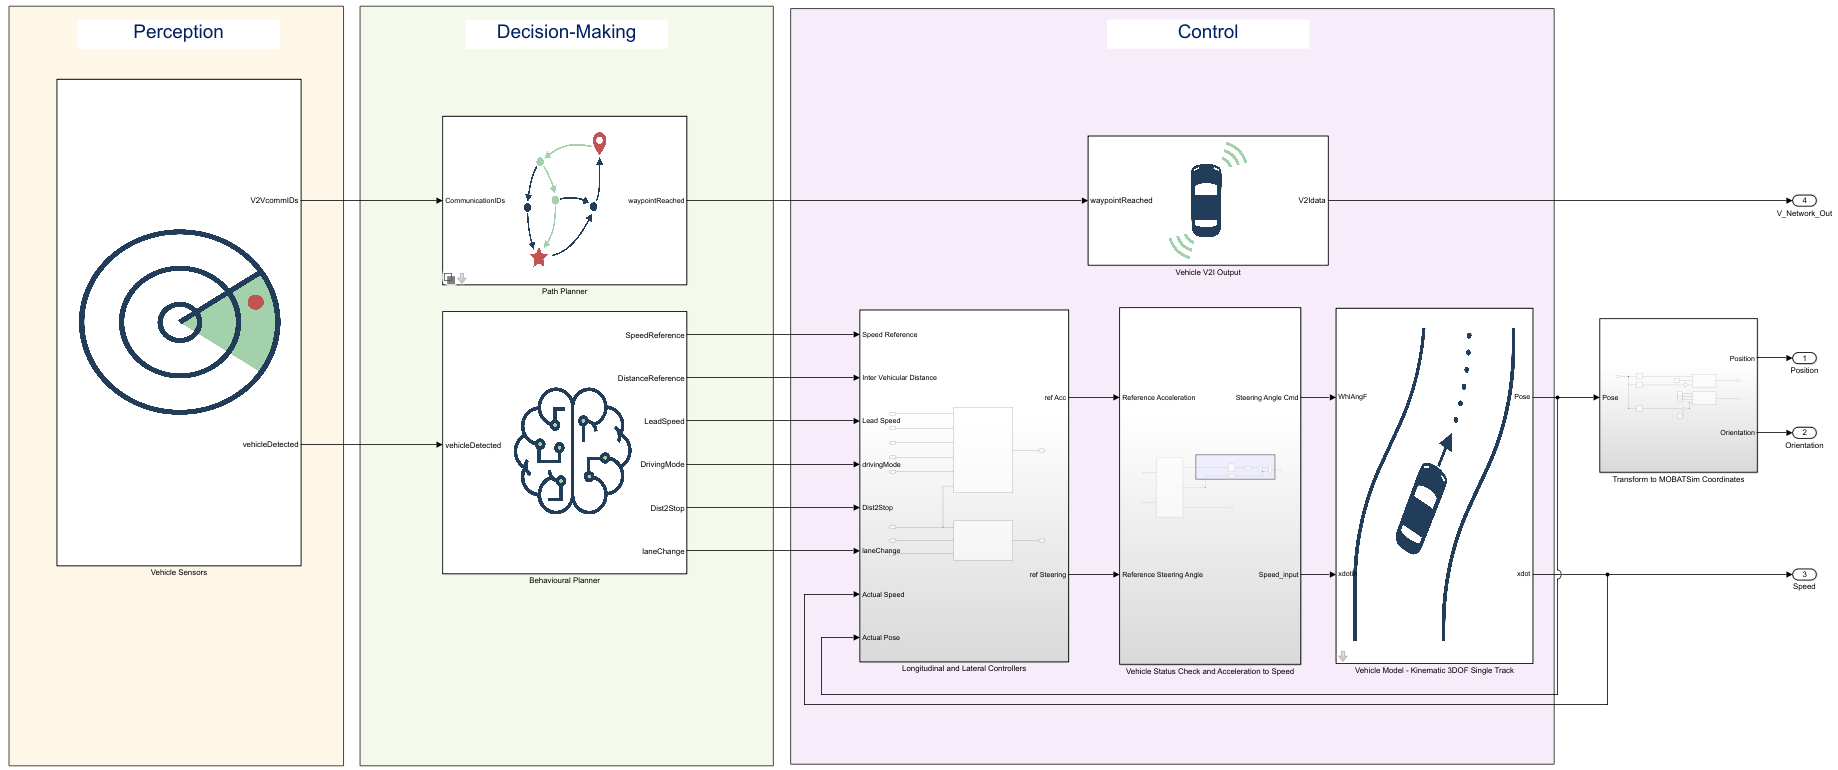

Next, select the *Behavioral Planner* block to set a breakpoint. Double-click on the *Behavioral Planner* block, and a small window will appear. Since this block is a MATLAB System block, it functions like a class with properties and methods. In this window, click on "Source code" to view the `src/Models and Classes/VehicleDrivingMode.m` class.

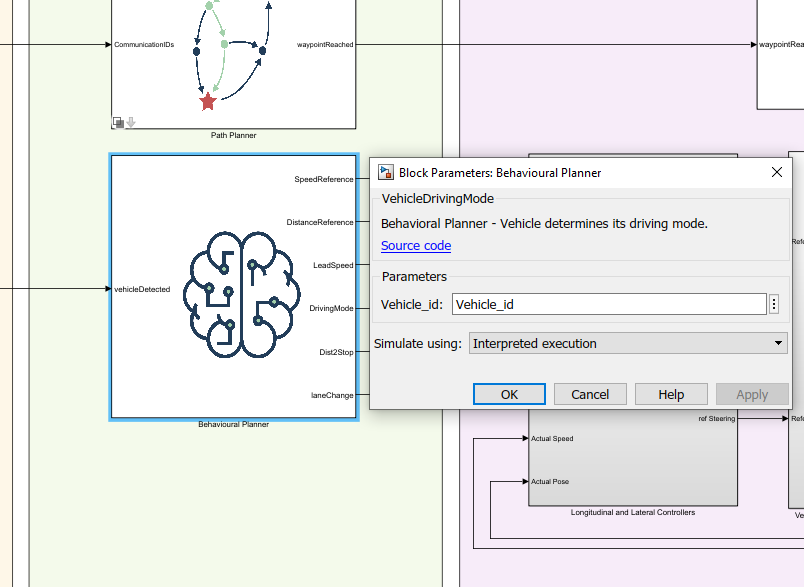

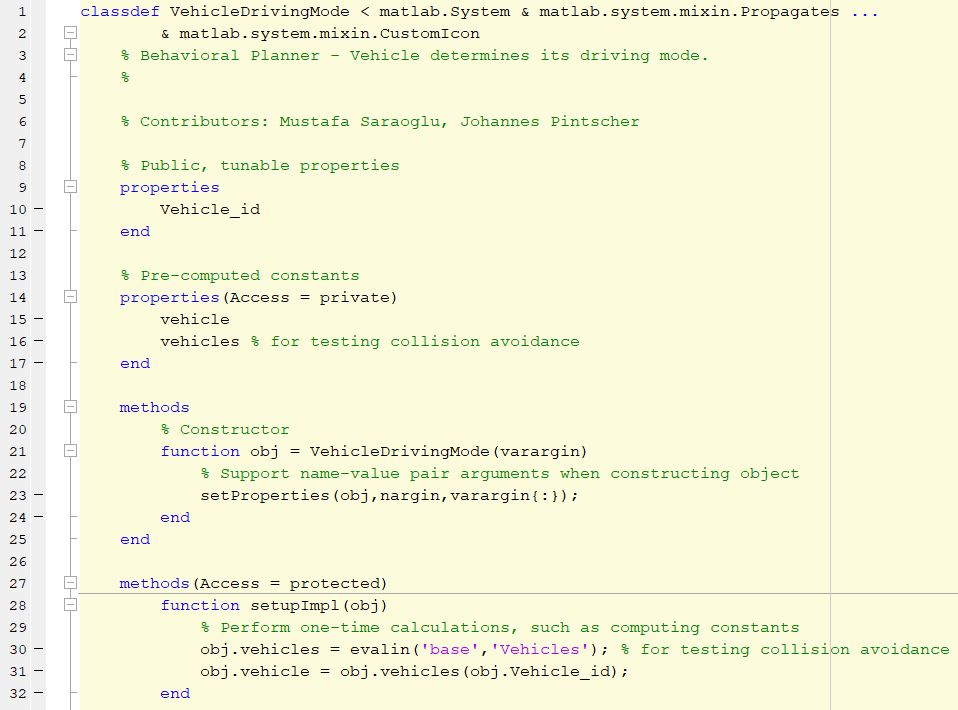

The `Vehicle_id` variable is used to ensure that the program does not confuse the IDs of different vehicles. The MATLAB System Block code, as seen in the editor, functions as a class but with a different set of properties to support Simulink block execution. To interrupt the block's execution at a specific time, navigate to the `stepImpl()` function, which runs in a loop at every sample time.

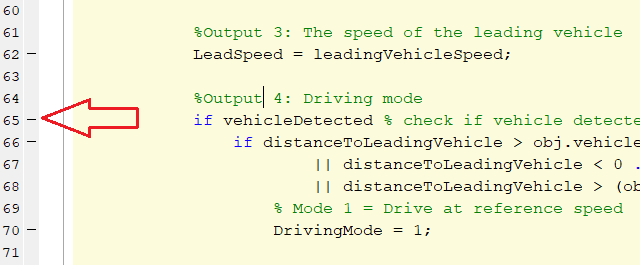

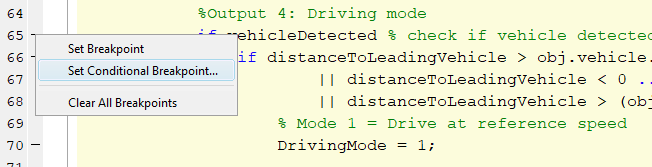

Let's set a conditional breakpoint on line 65. Right-click on the dash next to line number 65 on the left and select *Set Conditional Breakpoint*. A useful tip is to use conditional breakpoints to inspect the execution at a specific time. For example, to view the states of **Vehicle 4** after time` t>6`,  enter the following condition in the next window:

- `obj.vehicle.id == 4 && get_param('MOBATSim','SimulationTime')>6`

Here, `obj.vehicle.id` refers to the ID of the vehicle we want to access. The code `get_param('MOBATSim', 'SimulationTime') > 6` retrieves the simulation time of the Simulink model during each loop and checks if it is greater than 6. By using an `&&` (AND) operator between two conditions, we ensure that the simulation pauses when **Vehicle 4** executes the code after time `t>6`.

Now, simply run the simulation. By executing the code below or running the Simulink model through the GUI, the simulation will enter debugging mode.

The yellow dot indicates that the conditional breakpoint is set

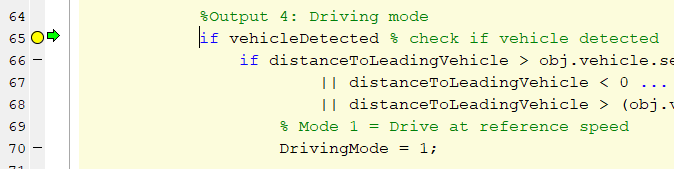

Now, we can check the states of **Vehicle 4** using the **Command Window** below. By typing `obj.vehicle.dynamics.speed`, we can check the current speed of **Vehicle 4** in m/s. To get a broader overview of** Vehicle 4**, simply type `obj.vehicle`, which will display the structure of the **Vehicle 4** object. For more details on the structure of a vehicle in MOBATSim, please refer to the `src/Models and Classes/Vehicle.m` class.

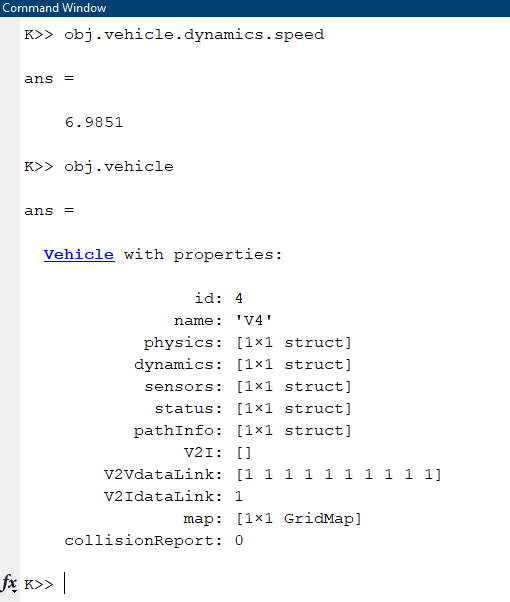

## 3- Injecting Faults into Vehicle X During the Simulation

In this Task, we can simply edit the Simulink model of a vehicle that we would like to and add a white noise source to the reference speed signal. Fault injection can be used to alter any of the signals in Simulink; therefore, this is just a simple example of examining the effects of a white noise disturbance on the vehicle's speed.

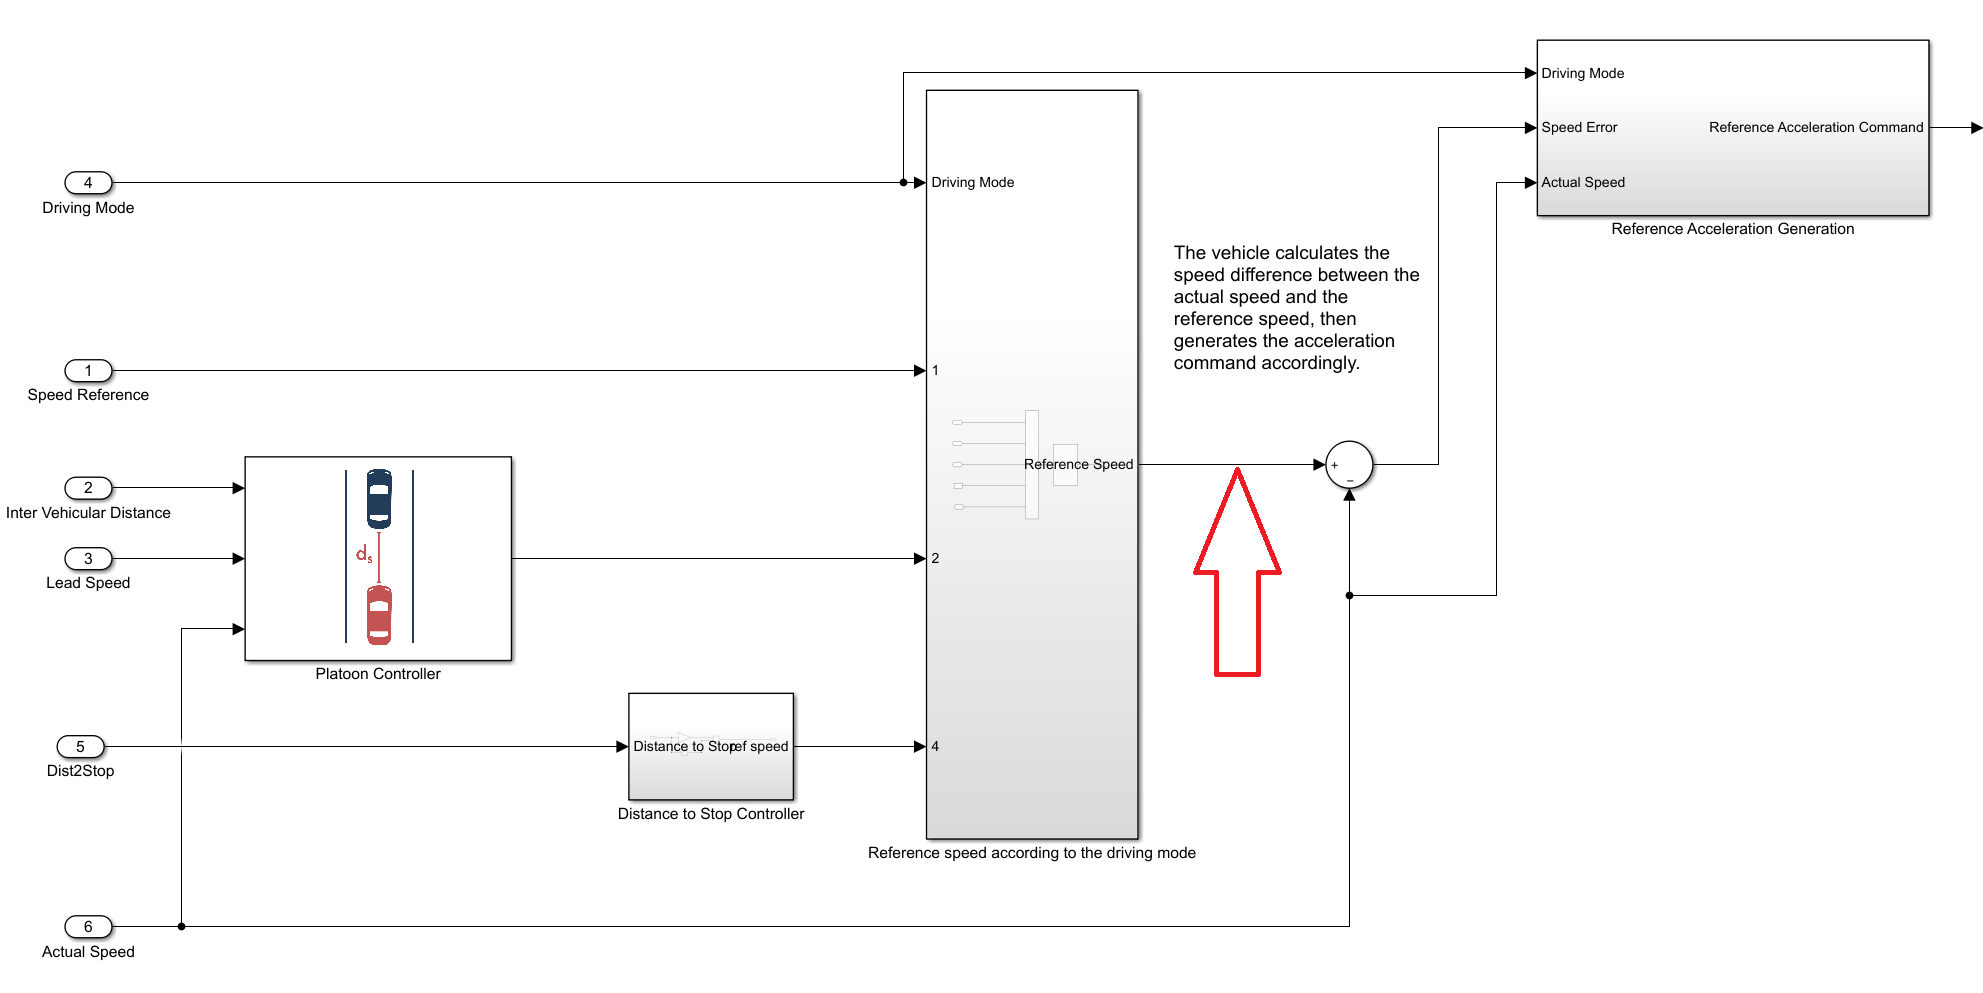

For the sake of simplicity, you can use a Band-Limited White Noise block and a sum block to inject faults. For more sophisticated fault injections, you can use a subsystem and/or a MATLAB function block.

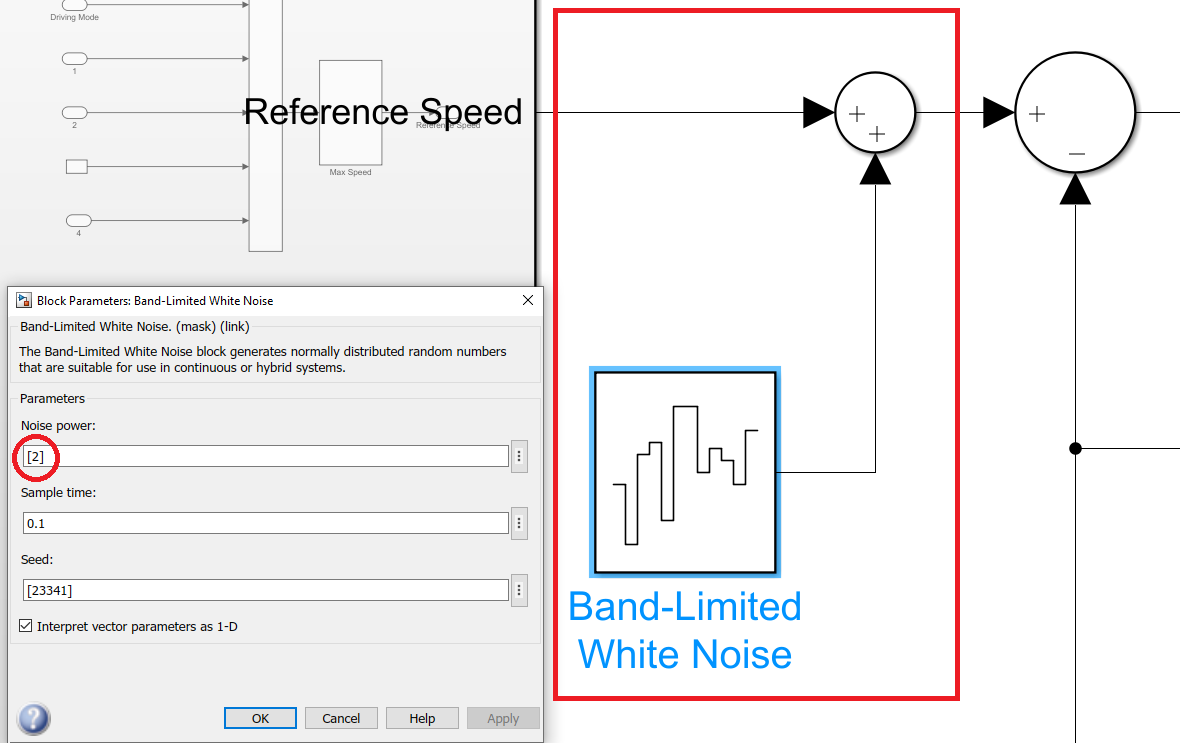

As we can see, even a noise with power **"2"** can cause higher deviations in the speed values.

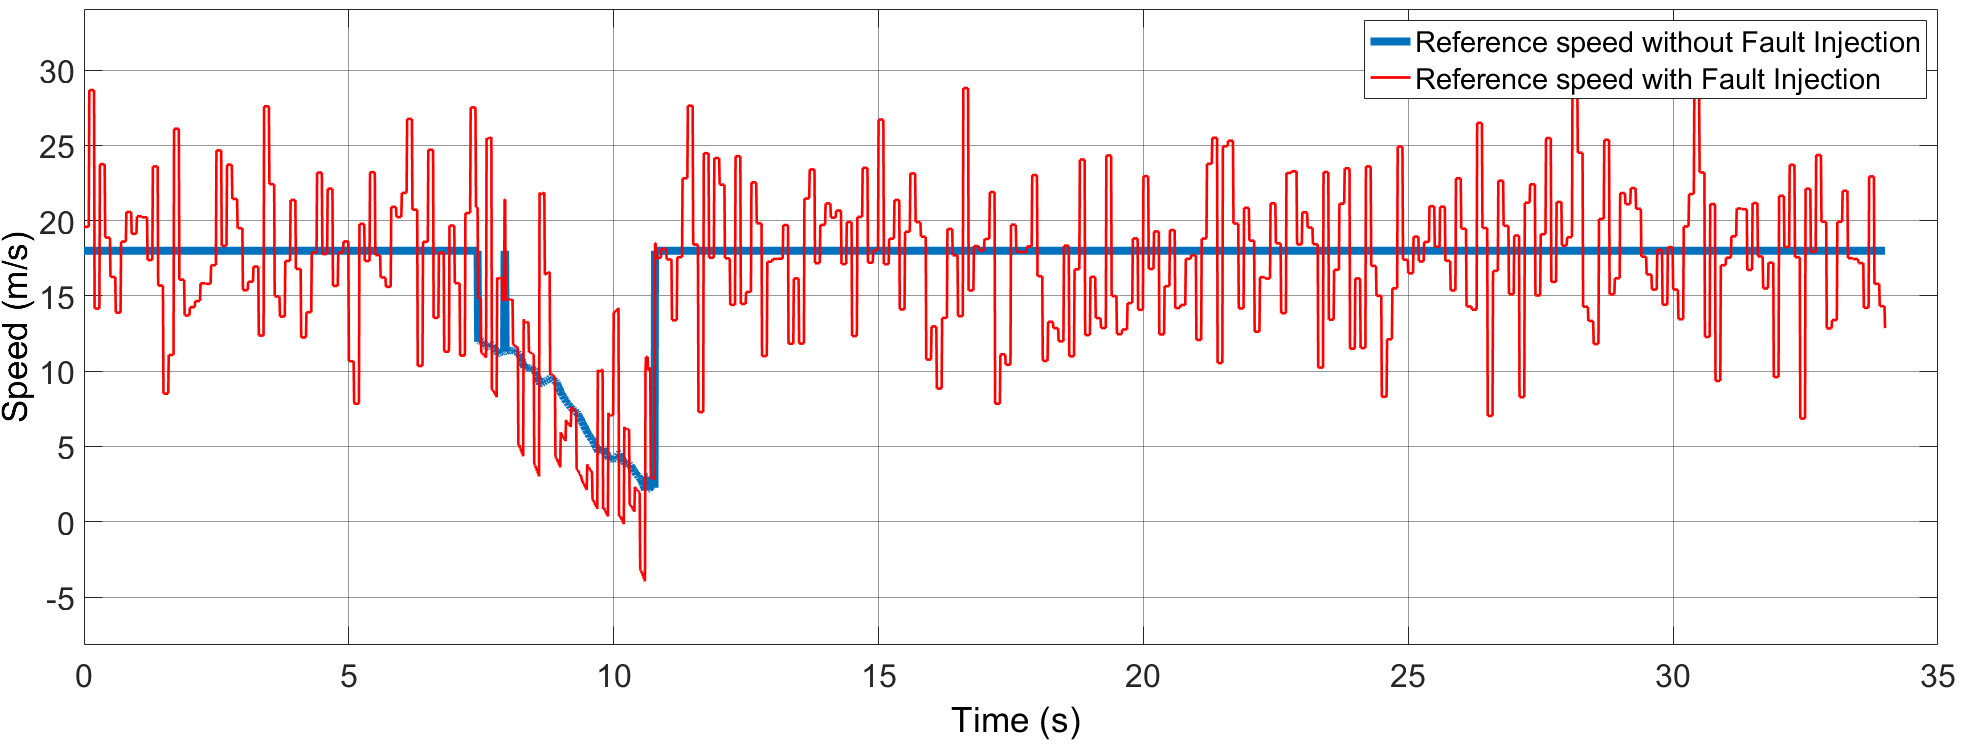

# -----------------------------------------------------------------------------

# Further Documentation

Please continue with the live script [Documentation.mlx](matlab:open('./docs\Documentation.mlx')) in the **docs** folder.